dataimporter

%norm_data_preparer

clear training_datain holdback_datain training holdback table

% 1-unrolls
% 2-numreg -2 /14
% 3-divint -4 /60
% 4-divindm -10 /118
% 5-central freq -250 /1500
% 6-time sampling
% 7-nchans
% 8-bw
% 9-min_dm_step
% 10-max_dm_step
% 11-max_dm
% 12-ndm_ranges

%-----Normalising values to use------
%unrolls_const
%{
unrolls = 4;

numreg_offset = 2;
numreg_div = 14;

divint_offset = 6;
divint_div = 60;

divindm_offset = 10;
divindm_div = 118;

cf_offset = 250;
cf_div = 1500;

tsamp_offset = 32;
tsamp_div = 992;

nchans_offset = 512;
nchans_div = 3584;

bw_offset = 50;
bw_div = 500;
%----------------------------------
%}
percentage = 30;

[training_datain,validations_datain] = holdback(monotonicDatain,percentage);
%[training_datain_271,holdback_datain_271] = holdback_271_only(datain,percentage);

%calculate the total number of observations and telescopes
training = featureTable271time(training_datain);
validation = featureTable271time(validations_datain);

table = [training;validation];


clear unrolls numreg_offset numreg_div divint_offset divint_div divindm_offset divindm_div tsamp_offset tsamp_div nchans_offset bw_div bw_offset cf_div cf_offset nchans_div

%holdback data



regression_layers = [
    featureInputLayer(12)
    %fullyConnectedLayer(30)
    %reluLayer
%     fullyConnectedLayer(8)
%     reluLayer
    fullyConnectedLayer(8)
    reluLayer
    fullyConnectedLayer(8)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];
 
%trainopts = trainingOptions('adam','MaxEpochs',100,'InitialLearnRate',0.0005,'Plots','training-progress','Shuffle','every-epoch');
%trainopts = trainingOptions('sgdm','MaxEpochs',100,'InitialLearnRate',0.001,'Plots','training-progress');
%net = trainNetwork(trainingTable2,'time_per_sample',regression_layers,trainopts);

[xt,yt] = table2array_splitter271(training(:,5:end));
[xv,yv] = table2array_splitter271(validation(:,5:end));

yv = nan_checker(yv);
yt = nan_checker(yt);

trainopts = trainingOptions('adam','MaxEpochs',5000, ...
            'InitialLearnRate',0.001,'Plots','training-progress', ...
            'MiniBatchSize',1000, 'Shuffle', 'every-epoch', ...
            'ValidationData',{xv,yv}, 'ValidationPatience',8, ...
            'ValidationFrequency', 25);
        
[regression_271, netinfo] = trainNetwork(xt,yt,regression_layers,trainopts)

Training on single GPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:14 |         0.45 |         0.41 |       0.0998 |       0.0830 |          0.0010 |


|      25 |          25 |       00:00:21 |         0.18 |         0.18 |       0.0165 |       0.0154 |          0.0010 |


|      50 |          50 |       00:00:25 |         0.13 |         0.13 |       0.0085 |       0.0089 |          0.0010 |


|      75 |          75 |       00:00:30 |         0.10 |         0.10 |       0.0054 |       0.0055 |          0.0010 |


|     100 |         100 |       00:00:34 |         0.09 |         0.09 |       0.0040 |       0.0042 |          0.0010 |


|     125 |         125 |       00:00:37 |         0.07 |         0.08 |       0.0028 |       0.0028 |          0.0010 |


|     150 |         150 |       00:00:37 |         0.06 |         0.06 |       0.0020 |       0.0021 |          0.0010 |


|     175 |         175 |       00:00:40 |         0.05 |         0.06 |       0.0015 |       0.0016 |          0.0010 |


|     200 |         200 |       00:00:44 |         0.05 |         0.05 |       0.0011 |       0.0012 |          0.0010 |


|     225 |         225 |       00:00:49 |         0.04 |         0.04 |       0.0009 |       0.0009 |          0.0010 |


|     250 |         250 |       00:00:55 |         0.04 |         0.04 |       0.0007 |       0.0007 |          0.0010 |


|     275 |         275 |       00:00:59 |         0.03 |         0.03 |       0.0005 |       0.0006 |          0.0010 |


|     300 |         300 |       00:01:03 |         0.03 |         0.03 |       0.0004 |       0.0005 |          0.0010 |


|     325 |         325 |       00:01:08 |         0.03 |         0.03 |       0.0004 |       0.0004 |          0.0010 |


|     350 |         350 |       00:01:10 |         0.03 |         0.03 |       0.0003 |       0.0004 |          0.0010 |


|     375 |         375 |       00:01:13 |         0.02 |         0.03 |       0.0003 |       0.0003 |          0.0010 |


|     400 |         400 |       00:01:14 |         0.02 |         0.02 |       0.0003 |       0.0003 |          0.0010 |


|     425 |         425 |       00:01:17 |         0.02 |         0.02 |       0.0002 |       0.0003 |          0.0010 |


|     450 |         450 |       00:01:22 |         0.02 |         0.02 |       0.0002 |       0.0002 |          0.0010 |


|     475 |         475 |       00:01:25 |         0.02 |         0.02 |       0.0002 |       0.0002 |          0.0010 |


|     500 |         500 |       00:01:28 |         0.02 |         0.02 |       0.0002 |       0.0002 |          0.0010 |


|     525 |         525 |       00:01:29 |         0.02 |         0.02 |       0.0002 |       0.0002 |          0.0010 |


|     550 |         550 |       00:01:32 |         0.02 |         0.02 |       0.0002 |       0.0002 |          0.0010 |


|     575 |         575 |       00:01:36 |         0.02 |         0.02 |       0.0002 |       0.0002 |          0.0010 |


|     600 |         600 |       00:01:39 |         0.02 |         0.02 |       0.0001 |       0.0002 |          0.0010 |


|     625 |         625 |       00:01:42 |         0.02 |         0.02 |       0.0001 |       0.0002 |          0.0010 |


|     650 |         650 |       00:01:43 |         0.02 |         0.02 |       0.0001 |       0.0002 |          0.0010 |


|     675 |         675 |       00:01:46 |         0.02 |         0.02 |       0.0001 |       0.0002 |          0.0010 |


|     700 |         700 |       00:01:49 |         0.02 |         0.02 |       0.0001 |       0.0001 |          0.0010 |


|     725 |         725 |       00:01:52 |         0.01 |         0.02 |       0.0001 |       0.0001 |          0.0010 |


|     750 |         750 |       00:01:56 |         0.01 |         0.02 |       0.0001 |       0.0001 |          0.0010 |


|     775 |         775 |       00:01:56 |         0.01 |         0.02 |   9.8075e-05 |       0.0001 |          0.0010 |


|     800 |         800 |       00:01:59 |         0.01 |         0.02 |   9.3657e-05 |       0.0001 |          0.0010 |


|     825 |         825 |       00:02:02 |         0.01 |         0.01 |   8.9757e-05 |       0.0001 |          0.0010 |


|     850 |         850 |       00:02:08 |         0.01 |         0.01 |   8.6254e-05 |       0.0001 |          0.0010 |


|     875 |         875 |       00:02:11 |         0.01 |         0.01 |   8.3063e-05 |   9.8536e-05 |          0.0010 |


|     900 |         900 |       00:02:11 |         0.01 |         0.01 |   8.0181e-05 |   9.3936e-05 |          0.0010 |


|     925 |         925 |       00:02:15 |         0.01 |         0.01 |   7.7569e-05 |   8.9769e-05 |          0.0010 |


|     950 |         950 |       00:02:18 |         0.01 |         0.01 |   7.5131e-05 |   8.6268e-05 |          0.0010 |


|     975 |         975 |       00:02:22 |         0.01 |         0.01 |   7.2784e-05 |   8.2967e-05 |          0.0010 |


|    1000 |        1000 |       00:02:25 |         0.01 |         0.01 |   7.0444e-05 |   7.9849e-05 |          0.0010 |


|    1025 |        1025 |       00:02:31 |         0.01 |         0.01 |   6.7900e-05 |   7.6867e-05 |          0.0010 |


|    1050 |        1050 |       00:02:34 |         0.01 |         0.01 |   6.5010e-05 |   7.3626e-05 |          0.0010 |


|    1075 |        1075 |       00:02:37 |         0.01 |         0.01 |   6.1876e-05 |   7.0346e-05 |          0.0010 |


|    1100 |        1100 |       00:02:37 |         0.01 |         0.01 |   5.9148e-05 |   6.7224e-05 |          0.0010 |


|    1125 |        1125 |       00:02:39 |         0.01 |         0.01 |   5.6547e-05 |   6.4380e-05 |          0.0010 |


|    1150 |        1150 |       00:02:41 |         0.01 |         0.01 |   5.4013e-05 |   6.1554e-05 |          0.0010 |


|    1175 |        1175 |       00:02:45 |         0.01 |         0.01 |   5.1348e-05 |   5.8603e-05 |          0.0010 |


|    1200 |        1200 |       00:02:48 |     9.87e-03 |         0.01 |   4.8707e-05 |   5.5628e-05 |          0.0010 |


|    1225 |        1225 |       00:02:48 |     9.65e-03 |         0.01 |   4.6577e-05 |   5.2560e-05 |          0.0010 |


|    1250 |        1250 |       00:02:52 |     9.45e-03 |     9.97e-03 |   4.4698e-05 |   4.9728e-05 |          0.0010 |


|    1275 |        1275 |       00:02:56 |     9.25e-03 |     9.70e-03 |   4.2810e-05 |   4.7090e-05 |          0.0010 |


|    1300 |        1300 |       00:02:58 |     9.08e-03 |     9.47e-03 |   4.1195e-05 |   4.4863e-05 |          0.0010 |


|    1325 |        1325 |       00:03:02 |     8.93e-03 |     9.29e-03 |   3.9829e-05 |   4.3172e-05 |          0.0010 |


|    1350 |        1350 |       00:03:06 |     8.78e-03 |     9.11e-03 |   3.8526e-05 |   4.1494e-05 |          0.0010 |


|    1375 |        1375 |       00:03:07 |     8.61e-03 |     8.90e-03 |   3.7092e-05 |   3.9639e-05 |          0.0010 |


|    1400 |        1400 |       00:03:09 |     8.46e-03 |     8.70e-03 |   3.5775e-05 |   3.7863e-05 |          0.0010 |


|    1425 |        1425 |       00:03:10 |     8.29e-03 |     8.51e-03 |   3.4372e-05 |   3.6232e-05 |          0.0010 |


|    1450 |        1450 |       00:03:12 |     8.12e-03 |     8.31e-03 |   3.2939e-05 |   3.4542e-05 |          0.0010 |


|    1475 |        1475 |       00:03:14 |     7.95e-03 |     8.13e-03 |   3.1631e-05 |   3.3024e-05 |          0.0010 |


|    1500 |        1500 |       00:03:14 |     7.80e-03 |     7.91e-03 |   3.0419e-05 |   3.1322e-05 |          0.0010 |


|    1525 |        1525 |       00:03:15 |     7.64e-03 |     7.63e-03 |   2.9149e-05 |   2.9088e-05 |          0.0010 |


|    1550 |        1550 |       00:03:18 |     7.45e-03 |     7.32e-03 |   2.7751e-05 |   2.6787e-05 |          0.0010 |


|    1575 |        1575 |       00:03:20 |     7.30e-03 |     7.07e-03 |   2.6652e-05 |   2.4982e-05 |          0.0010 |


|    1600 |        1600 |       00:03:22 |     7.15e-03 |     6.81e-03 |   2.5588e-05 |   2.3173e-05 |          0.0010 |


|    1625 |        1625 |       00:03:22 |     7.01e-03 |     6.56e-03 |   2.4582e-05 |   2.1527e-05 |          0.0010 |


|    1650 |        1650 |       00:03:24 |     6.91e-03 |     6.39e-03 |   2.3886e-05 |   2.0430e-05 |          0.0010 |


|    1675 |        1675 |       00:03:25 |     6.81e-03 |     6.21e-03 |   2.3216e-05 |   1.9289e-05 |          0.0010 |


|    1700 |        1700 |       00:03:28 |     6.70e-03 |     5.98e-03 |   2.2416e-05 |   1.7862e-05 |          0.0010 |


|    1725 |        1725 |       00:03:28 |     6.59e-03 |     5.78e-03 |   2.1732e-05 |   1.6680e-05 |          0.0010 |


|    1750 |        1750 |       00:03:30 |     6.52e-03 |     5.63e-03 |   2.1257e-05 |   1.5860e-05 |          0.0010 |


|    1775 |        1775 |       00:03:32 |     6.46e-03 |     5.52e-03 |   2.0864e-05 |   1.5219e-05 |          0.0010 |


|    1800 |        1800 |       00:03:34 |     6.40e-03 |     5.40e-03 |   2.0503e-05 |   1.4604e-05 |          0.0010 |


|    1825 |        1825 |       00:03:36 |     6.36e-03 |     5.32e-03 |   2.0219e-05 |   1.4133e-05 |          0.0010 |


|    1850 |        1850 |       00:03:36 |     6.32e-03 |     5.24e-03 |   1.9972e-05 |   1.3742e-05 |          0.0010 |


|    1875 |        1875 |       00:03:38 |     6.28e-03 |     5.16e-03 |   1.9729e-05 |   1.3325e-05 |          0.0010 |


|    1900 |        1900 |       00:03:40 |     6.24e-03 |     5.08e-03 |   1.9491e-05 |   1.2914e-05 |          0.0010 |


|    1925 |        1925 |       00:03:41 |     6.20e-03 |     5.00e-03 |   1.9248e-05 |   1.2488e-05 |          0.0010 |


|    1950 |        1950 |       00:03:42 |     6.16e-03 |     4.90e-03 |   1.8967e-05 |   1.2017e-05 |          0.0010 |


|    1975 |        1975 |       00:03:43 |     6.12e-03 |     4.82e-03 |   1.8699e-05 |   1.1614e-05 |          0.0010 |


|    2000 |        2000 |       00:03:45 |     6.07e-03 |     4.75e-03 |   1.8442e-05 |   1.1268e-05 |          0.0010 |


|    2025 |        2025 |       00:03:46 |     6.03e-03 |     4.69e-03 |   1.8204e-05 |   1.0980e-05 |          0.0010 |


|    2050 |        2050 |       00:03:47 |     6.00e-03 |     4.63e-03 |   1.7980e-05 |   1.0727e-05 |          0.0010 |


|    2075 |        2075 |       00:03:48 |     5.97e-03 |     4.59e-03 |   1.7791e-05 |   1.0526e-05 |          0.0010 |


|    2100 |        2100 |       00:03:50 |     5.93e-03 |     4.53e-03 |   1.7606e-05 |   1.0281e-05 |          0.0010 |


|    2125 |        2125 |       00:03:51 |     5.91e-03 |     4.50e-03 |   1.7453e-05 |   1.0133e-05 |          0.0010 |


|    2150 |        2150 |       00:03:53 |     5.88e-03 |     4.47e-03 |   1.7313e-05 |   9.9816e-06 |          0.0010 |


|    2175 |        2175 |       00:03:54 |     5.86e-03 |     4.44e-03 |   1.7178e-05 |   9.8423e-06 |          0.0010 |


|    2200 |        2200 |       00:03:55 |     5.84e-03 |     4.41e-03 |   1.7057e-05 |   9.7169e-06 |          0.0010 |


|    2225 |        2225 |       00:03:56 |     5.82e-03 |     4.38e-03 |   1.6941e-05 |   9.5979e-06 |          0.0010 |


|    2250 |        2250 |       00:03:58 |     5.80e-03 |     4.36e-03 |   1.6824e-05 |   9.4860e-06 |          0.0010 |


|    2275 |        2275 |       00:03:59 |     5.78e-03 |     4.33e-03 |   1.6716e-05 |   9.3822e-06 |          0.0010 |


|    2300 |        2300 |       00:04:00 |     5.76e-03 |     4.29e-03 |   1.6571e-05 |   9.1906e-06 |          0.0010 |


|    2325 |        2325 |       00:04:02 |     5.73e-03 |     4.24e-03 |   1.6429e-05 |   8.9935e-06 |          0.0010 |


|    2350 |        2350 |       00:04:03 |     5.71e-03 |     4.20e-03 |   1.6296e-05 |   8.8280e-06 |          0.0010 |


|    2375 |        2375 |       00:04:05 |     5.68e-03 |     4.17e-03 |   1.6159e-05 |   8.6782e-06 |          0.0010 |


|    2400 |        2400 |       00:04:07 |     5.66e-03 |     4.12e-03 |   1.6008e-05 |   8.4969e-06 |          0.0010 |


|    2425 |        2425 |       00:04:07 |     5.63e-03 |     4.08e-03 |   1.5866e-05 |   8.3186e-06 |          0.0010 |


|    2450 |        2450 |       00:04:09 |     5.61e-03 |     4.04e-03 |   1.5736e-05 |   8.1730e-06 |          0.0010 |


|    2475 |        2475 |       00:04:10 |     5.59e-03 |     4.03e-03 |   1.5619e-05 |   8.1118e-06 |          0.0010 |


|    2500 |        2500 |       00:04:12 |     5.57e-03 |     4.02e-03 |   1.5502e-05 |   8.0609e-06 |          0.0010 |


|    2525 |        2525 |       00:04:12 |     5.55e-03 |     4.01e-03 |   1.5375e-05 |   8.0230e-06 |          0.0010 |


|    2550 |        2550 |       00:04:15 |     5.52e-03 |     4.00e-03 |   1.5258e-05 |   7.9907e-06 |          0.0010 |


|    2575 |        2575 |       00:04:17 |     5.51e-03 |     3.99e-03 |   1.5156e-05 |   7.9545e-06 |          0.0010 |


|    2600 |        2600 |       00:04:18 |     5.49e-03 |     3.98e-03 |   1.5068e-05 |   7.9231e-06 |          0.0010 |


|    2625 |        2625 |       00:04:19 |     5.47e-03 |     3.97e-03 |   1.4986e-05 |   7.8935e-06 |          0.0010 |


|    2650 |        2650 |       00:04:21 |     5.46e-03 |     3.97e-03 |   1.4911e-05 |   7.8658e-06 |          0.0010 |


|    2675 |        2675 |       00:04:22 |     5.45e-03 |     3.96e-03 |   1.4840e-05 |   7.8408e-06 |          0.0010 |


|    2700 |        2700 |       00:04:24 |     5.44e-03 |     3.95e-03 |   1.4776e-05 |   7.8193e-06 |          0.0010 |


|    2725 |        2725 |       00:04:25 |     5.43e-03 |     3.95e-03 |   1.4717e-05 |   7.8017e-06 |          0.0010 |


|    2750 |        2750 |       00:04:26 |     5.41e-03 |     3.95e-03 |   1.4659e-05 |   7.7826e-06 |          0.0010 |


|    2775 |        2775 |       00:04:28 |     5.40e-03 |     3.94e-03 |   1.4604e-05 |   7.7658e-06 |          0.0010 |


|    2800 |        2800 |       00:04:30 |     5.39e-03 |     3.94e-03 |   1.4544e-05 |   7.7430e-06 |          0.0010 |


|    2825 |        2825 |       00:04:31 |     5.38e-03 |     3.93e-03 |   1.4480e-05 |   7.7080e-06 |          0.0010 |


|    2850 |        2850 |       00:04:32 |     5.37e-03 |     3.92e-03 |   1.4420e-05 |   7.6744e-06 |          0.0010 |


|    2875 |        2875 |       00:04:33 |     5.36e-03 |     3.91e-03 |   1.4361e-05 |   7.6343e-06 |          0.0010 |


|    2900 |        2900 |       00:04:35 |     5.35e-03 |     3.90e-03 |   1.4308e-05 |   7.6027e-06 |          0.0010 |


|    2925 |        2925 |       00:04:36 |     5.34e-03 |     3.89e-03 |   1.4255e-05 |   7.5707e-06 |          0.0010 |


|    2950 |        2950 |       00:04:38 |     5.33e-03 |     3.87e-03 |   1.4191e-05 |   7.5046e-06 |          0.0010 |


|    2975 |        2975 |       00:04:38 |     5.32e-03 |     3.87e-03 |   1.4138e-05 |   7.4731e-06 |          0.0010 |


|    3000 |        3000 |       00:04:40 |     5.31e-03 |     3.86e-03 |   1.4096e-05 |   7.4629e-06 |          0.0010 |


|    3025 |        3025 |       00:04:42 |     5.30e-03 |     3.86e-03 |   1.4056e-05 |   7.4534e-06 |          0.0010 |


|    3050 |        3050 |       00:04:43 |     5.29e-03 |     3.86e-03 |   1.4015e-05 |   7.4419e-06 |          0.0010 |


|    3075 |        3075 |       00:04:44 |     5.29e-03 |     3.86e-03 |   1.3973e-05 |   7.4313e-06 |          0.0010 |


|    3100 |        3100 |       00:04:45 |     5.28e-03 |     3.85e-03 |   1.3929e-05 |   7.4100e-06 |          0.0010 |


|    3125 |        3125 |       00:04:47 |     5.27e-03 |     3.84e-03 |   1.3883e-05 |   7.3655e-06 |          0.0010 |


|    3150 |        3150 |       00:04:49 |     5.26e-03 |     3.84e-03 |   1.3852e-05 |   7.3879e-06 |          0.0010 |


|    3175 |        3175 |       00:04:51 |     5.26e-03 |     3.85e-03 |   1.3822e-05 |   7.4057e-06 |          0.0010 |


|    3200 |        3200 |       00:04:51 |     5.25e-03 |     3.85e-03 |   1.3792e-05 |   7.4092e-06 |          0.0010 |


|    3225 |        3225 |       00:04:53 |     5.25e-03 |     3.85e-03 |   1.3756e-05 |   7.4071e-06 |          0.0010 |


|    3250 |        3250 |       00:04:54 |     5.24e-03 |     3.86e-03 |   1.3722e-05 |   7.4331e-06 |          0.0010 |


|    3275 |        3275 |       00:04:56 |     5.23e-03 |     3.86e-03 |   1.3684e-05 |   7.4676e-06 |          0.0010 |


|    3300 |        3300 |       00:04:56 |     5.23e-03 |     3.87e-03 |   1.3663e-05 |   7.5046e-06 |          0.0010 |


|    3325 |        3325 |       00:04:59 |     5.22e-03 |     3.88e-03 |   1.3643e-05 |   7.5327e-06 |          0.0010 |


|======================================================================================================================|


regression_271 =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


netinfo = struct with fields:
           TrainingLoss: [1×3325 double]
           TrainingRMSE: [1×3325 double]
         ValidationLoss: [1×3325 double]
         ValidationRMSE: [1×3325 double]
          BaseLearnRate: [1×3325 double]
    FinalValidationLoss: 7.5327e-06
    FinalValidationRMSE: 0.0039


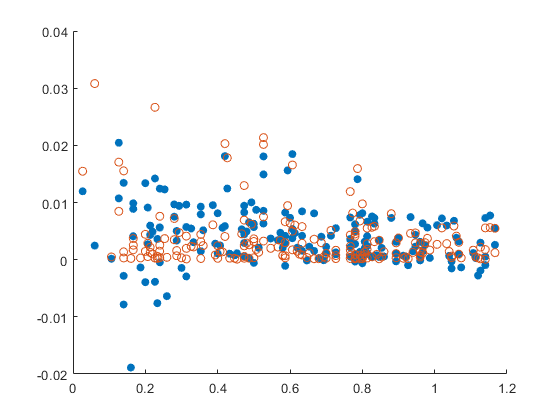

Error using scatter (line 72)
X and Y must be vectors of the same length.

Error in timenetwork271>plotting (line 136)
    scatter(xv(:,1),xv - predictions)

%net = trainNetwork(fullfeatures,values,regression_layers,trainopts);
plotting(regression_271,xv,yv)

%net_stats7 = stats(net7, holdback_datain, holdbackTable, 2)

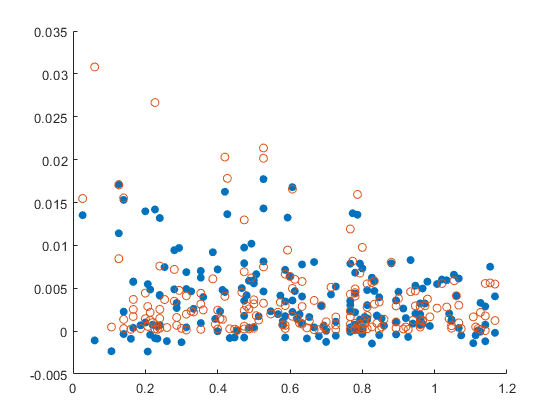

meanerror = single
-2.2970e-04

rmserror = single
0.0032

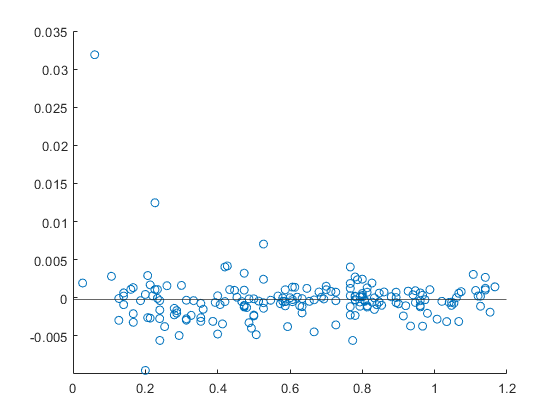

plotting(regression_271,xv,yv)

regression_layers = [
    featureInputLayer(12)
    %fullyConnectedLayer(30)
    %reluLayer
%     fullyConnectedLayer(8)
%     reluLayer
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(8)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];
 
%trainopts = trainingOptions('adam','MaxEpochs',100,'InitialLearnRate',0.0005,'Plots','training-progress','Shuffle','every-epoch');
%trainopts = trainingOptions('sgdm','MaxEpochs',100,'InitialLearnRate',0.001,'Plots','training-progress');
%net = trainNetwork(trainingTable2,'time_per_sample',regression_layers,trainopts);

[xt,yt] = table2array_splitter271(training(:,5:end));
[xv,yv] = table2array_splitter271(validation(:,5:end));

yv = nan_checker(yv);
yt = nan_checker(yt);

trainopts = trainingOptions('adam','MaxEpochs',5000, ...
            'InitialLearnRate',0.001,'Plots','none', ...
            'MiniBatchSize',128, 'Shuffle', 'every-epoch', ...
            'ValidationData',{xv,yv}, 'ValidationPatience',8, ...
            'ValidationFrequency', 25);
        
[regression_271, netinfo] = trainNetwork(xt,yt,regression_layers,trainopts)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |         1.72 |         1.69 |       1.4774 |       1.4343 |          0.0010 |
|       9 |          25 |       00:00:00 |         1.67 |         1.68 |       1.3936 |       1.4146 |          0.0010 |
|      17 |          50 |       00:00:00 |         1.76 |         1.67 |       1.5557 |       1.3959 |          0.0010 |
|      25 |          75 |       00:00:01 |         1.69 |         1.66 |       1.4364 |       1.3795 |          0.0010 |
|      3

regression_271 =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


netinfo = struct with fields:
           TrainingLoss: [1×450 double]
           TrainingRMSE: [1×450 double]
         ValidationLoss: [1×450 double]
         ValidationRMSE: [1×450 double]
          BaseLearnRate: [1×450 double]
    FinalValidationLoss: 1.5306
    FinalValidationRMSE: 1.7496


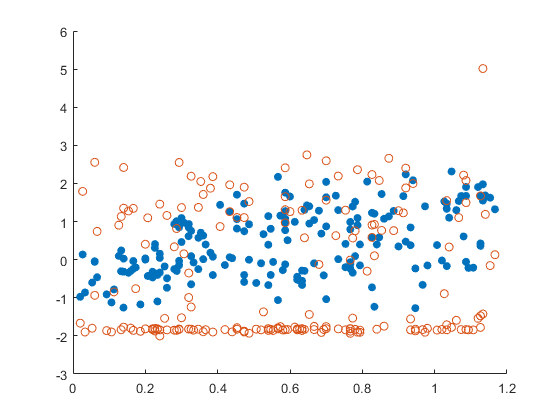

meanerror = single
-0.8918

rmserror = single
1.7496

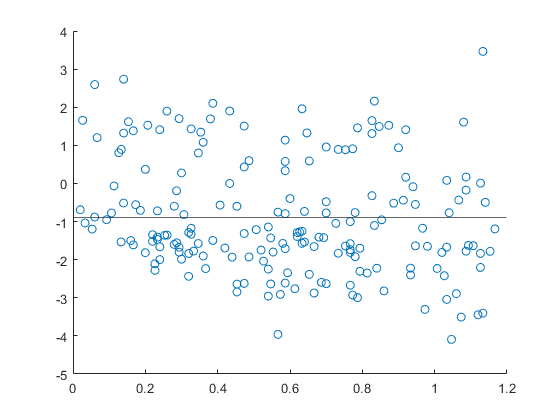

%net = trainNetwork(fullfeatures,values,regression_layers,trainopts);
plotting(regression_271,xv,yv)

%net_stats7 = stats(net7, holdback_datain, holdbackTable, 2)

function plotting(network,xv,yv)
    figure(1)
    predictions = predict(network,xv);
    scatter(xv(:,1),predictions,'filled')
    hold on 
    scatter(xv(:,1),yv)
    hold off
    figure(2)
    scatter(xv(:,1),yv - predictions)
    hold on
    yline(mean(yv - predictions))
    meanerror = mean(yv - predictions)
    rmserror = sqrt(meansqr(yv - predictions))
    hold off
end

